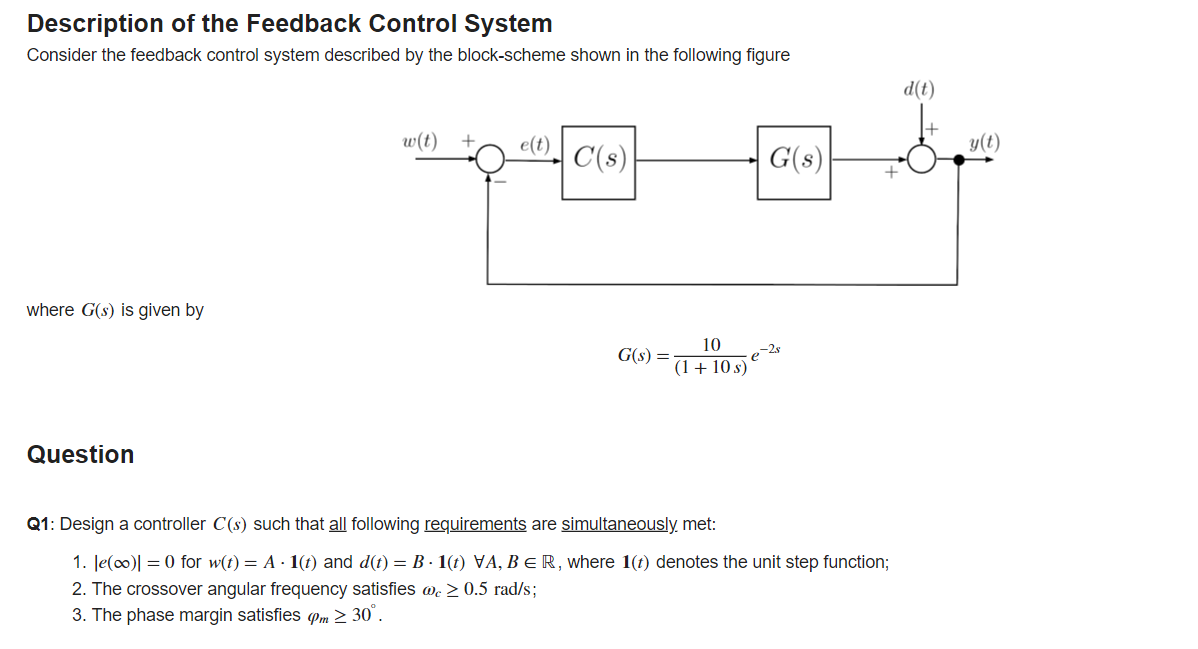

**ANALISI PRELIMINARE**

Il solo processo descritto dalla funzione di trasferimento G(s) porta ad un sistema con caratteristiche:

- margine di fase $\varphi_m= -18.3\degree $

- pulsazione critica $\omega_c = 0.995$ rad/s

- sistema di tipo 0

Ovviamente non soddisfa le specifiche. 

Progettiamo un regolatore della forma $C(s) = C_1(s) C_2(s)$ dove $C_1(s)$ è progettato per soddisfare la prima specifica (comportamento statico) e $C_2(s)$ è progettato per soddisfare la seconda e terza specifica (comportamento dinamico).

**PROGETTO STATICO**

Per rispettare il primo requisito (Q1.1) la funzione di trasferimento $L(s)$ deve essere di tipo $g \ge 1$. Consideriamo $g=1$ per tenere il controllore il più semplice possibile

Dunque, imponiamo $C_1(s) = \frac{\mu_c}{s}$ 

A questo punto, prima di modificare il controllore in modo da rispettare i requisiti dinamici, studiamo la FdT $G(s)$

Consideriamo un generico $\tilde{\omega}$, abbiamo

$|G(j\omega) = |\frac{10}{1+10j\omega}| \cdot |e^{(-2j\omega)}|$  dove $\tilde{G}(j\omega)= \frac{10}{1+10j\omega}$

Considerando ciò, possiamo scrivere


$$arg \ G(j\omega) = arg \ \tilde{G}(j\omega) + arg \ e^{-2j\omega}$$


A  questo punto, possiamo procedere studiando la funzione $\tilde{G}(s)$ però dobbiamo modificare i requisiti

(Q1.2) Rimane invariato perchè il termine $e^{-2s}$ non fa variare il termine $\omega_c$

(Q1.3) Dobbiamo invece modificare questo requisito e imporre che $\varphi_c \ge 30\degree  + arg \ e^{-2s}$

A questo punto, possiamo iniziare il progetto dinamico, ovvero modificare il controllore per soddisfare gli ultimi due requisiti

**PROGETTO DINAMICO**

Procediamo per cancellazione dinamica del processo e imponiamo che 


$$\left\{ \begin{array}{rcl}
C_1(s) &=& \frac{\mu_C}{s}\\
C_2(s) &=& (1+10s) \\
C(s) &=& C_1(s) \cdot C_2(s) = \mu_C \, \frac{1+10s}{s}
\end{array} \right. \quad \Longrightarrow \quad 
\tilde{L}(s) = C(s) \cdot \tilde{G}(s) = \frac{10 \mu_C}{s}\,\frac{1+10s}{1+10s} = \frac{10\mu_C}{s}$$


A questo punto sappiamo 


$$\left\{ \begin{array}{rcl}
\varphi_m \ge 30\degree  + arg e^{-2j\omega} \\
\varphi_m = \varphi_c- (-180\degree ) \\ 
\end{array}$$
  
$$\Longrightarrow$$
 
$$\varphi_c \ge -150\degree  + arg \ e^{-2j\omega_c}$$


Però, avendo imposto il controllore come segue abbiamo $\varphi_c = -90\degree $

Dobbiamo trovare un valore di $\omega_c$ tale che 


$$\bar{\omega}: \bar{\omega} \ge \frac{1}{2}\,,\quad -90^{\degree} \ge -150^{\degree} + 2 \bar{\omega} \, \frac{180^{\degree}}{\pi} \quad 
\Longrightarrow \quad
\bar{\omega} \le 60^{\degree}\cdot \frac{\pi}{360^{\degree}} = \frac{\pi}{6} \approx 0.52 \; \text{rad/s}$$


A questo punto, imponiamo $\omega_c = \frac{\pi}{6}$ per trovare il valore adeguato di $\mu_c$


$$|L(j\omega_c)| = 1 \ \ \Longrightarrow \ \ \frac {|10\mu_c|}{|j\omega_c|} = 1$$


Dopo un facile conto otteniamo che il valore desiderato è $\mu_c = 0.052$

Il controllore che abbiamo ottenuto è il seguente


$$C(s) = C_1(s) C_2(s) = \frac{0.052(1+10s)}{s}$$


Riportiamo i risultati appena ottenuti 

s=tf('s');

Gtilde = 10/(1+10*s); % the process TF WITHOUT THE DELAY TERM
Gs = Gtilde*exp(-2*s) % the complete process TF 

Gs =
 
                 10
  exp(-2*s) * --------
              10 s + 1
 
Continuous-time transfer function.
Model Properties



muC = 0.052;
C1s = muC/s;
C2s = (1+10*s);
Cs = C1s*C2s;

Ltilde_s = minreal(Cs * Gtilde)

Ltilde_s =
 
  0.52
  ----
   s
 
Continuous-time transfer function.
Model Properties



Ls = minreal(Cs * Gs)

Ls =
 
              0.52
  exp(-2*s) * ----
               s
 
Continuous-time transfer function.
Model Properties


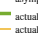


omVALS = logspace(-2,2, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

% straight-line approximation and actuual Bode diagrams of Ltilde(s)
[hax1, hax2] = drawBodediagrams(Ltilde_s, omVALS, Bcolors(1, :), 3.5, '-', ...
                       Bcolors(4, :), 2.5, '-', hf);

% actuual Bode diagrams of L(s)
[L_Mag, L_Phase] = bode(Ls, omVALS);
L_Mag_dB = 20*log10(L_Mag(:));
plot(hax1, omVALS, L_Mag_dB, 'Color', Bcolors(2, :),...
     'LineWidth', 1.0, 'LineStyle', '-');
plot(hax2, omVALS, L_Phase(:), 'Color', Bcolors(2, :),...
     'LineWidth', 1.0, 'LineStyle', '-');
ylim(hax2,[-360,  -80]);

% let's eval the frequency response of Ltilde(s) and L(s) at the angular
% frequency bar_omega = 0.5
OMEGAc = 0.52;
FrResp05 = freqresp(Ls, OMEGAc); % freq. resp. L(s)
L05Mag = 20*log10(abs(FrResp05));
L05Phase = rad2deg(angle(FrResp05)); 
FrRespTilde05 = freqresp(Ltilde_s, OMEGAc); % freq. resp. Ltilde(s)
LTilde05Mag = 20*log10(abs(FrRespTilde05));
LTilde05Phase = rad2deg(angle(FrRespTilde05)); 

% magnitude & phase for Ltilde(j0.5) and L(j0.5)
plot(hax1, OMEGAc, LTilde05Mag, 'Marker','square','MarkerSize',10, ...
      'MarkerEdgeColor',Bcolors(4, :), ...
      'MarkerFaceColor', Bcolors(4, :), ...
      'LineStyle','none');

plot(hax1, OMEGAc, L05Mag, 'Marker','o','MarkerSize',6, ...
      'MarkerEdgeColor',Bcolors(2, :), ...
      'MarkerFaceColor', Bcolors(2, :), ...
      'LineStyle','none');

plot(hax2, OMEGAc, LTilde05Phase, 'Marker','square','MarkerSize',10, ...
      'MarkerEdgeColor',Bcolors(4, :), ...
      'MarkerFaceColor', Bcolors(4, :), ...
      'LineStyle','none');

plot(hax2, OMEGAc, L05Phase, 'Marker','o','MarkerSize',6, ...
      'MarkerEdgeColor',Bcolors(2, :), ...
      'MarkerFaceColor', Bcolors(2, :), ...
      'LineStyle','none');


legend(hax1, 'asympt. $\tilde{L}(s)$', 'actual $\tilde{L}(s)$', ...
             'actual $L(s)$', '$\tilde{L}(j \omega_c)$', '$L(j \omega_c)$',...
             'Interpreter', 'latex', ...
             'Location', 'best');

legend(hax2,  'asympt. $\tilde{L}(s)$', 'actual $\tilde{L}(s)$', ...
             'actual $L(s)$', '$\tilde{L}(j \omega_c)$', '$L(j \omega_c)$',...
             'Interpreter', 'latex', ...
             'Location', 'best');

Verifichiamo i risultati ottenuti mediante **Control System Design App**

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties



% Define the function G(s)

Gs = (10*exp(-2*s))/(1+10*s)

Gs =
 
                 10
  exp(-2*s) * --------
              10 s + 1
 
Continuous-time transfer function.
Model Properties



% Define the controller C(s)

Cs = (0.052*(1+10*s))/(s)

Cs =
 
  0.52 s + 0.052
  --------------
        s
 
Continuous-time transfer function.
Model Properties



% Verify the result obtained

controlSystemDesigner(Gs,Cs)
